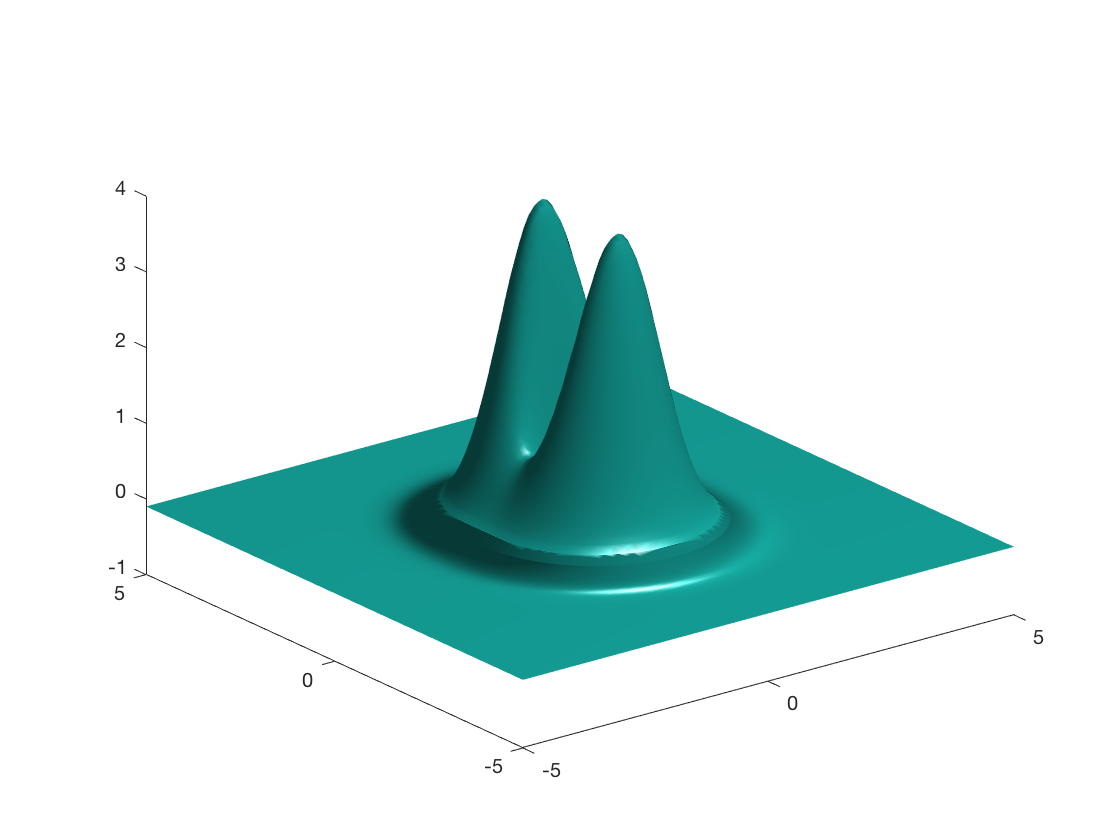

[X,Y,Z] = meshgrid(-5:0.1:5,-5:0.1:5,-5:0.1:5);
V = ((X.^2 + 4.*Y.^2) .* exp(1 - X.^2 - Y.^2))./(Z);
isosurface(X,Y,Z,V,1)
hold on


clear
syms x y
F = (x.^2 + 4*y.^2) * exp(1 - x.^2 - y.^2);
Fx = diff(F,x);
Fy = diff(F,y);
[x0,y0] = solve(Fx,Fy,x,y); [x0,y0]

$$ans = \left(\begin{array}{cc} 0 & 0\\ -1 & 0\\ 1 & 0\\ 0 & -1\\ 0 & 1 \end{array}\right)$$

Fxx = diff(Fx,x);
Fyy = diff(Fy,y);
Fxy = diff(Fx,y);
D = Fxx*Fyy - (Fxy)^2;

D1 = subs(D,{x,y},{x0(1),y0(1)});
Fxx1 = subs(Fxx,{x,y},{x0(1),y0(1)});
z1 = subs(F,{x,y},{x0(1),y0(1)})

$$z1 = 0$$

D2 = subs(D,{x,y},{x0(2),y0(2)});
Fxx2 = subs(Fxx,{x,y},{x0(2),y0(2)});
z2 = subs(F,{x,y},{x0(2),y0(2)})

$$z2 = 1$$

D3 = subs(D,{x,y},{x0(3),y0(3)});
Fxx3 = subs(Fxx,{x,y},{x0(3),y0(3)});
z3 = subs(F,{x,y},{x0(3),y0(3)})

$$z3 = 1$$

D4 = subs(D,{x,y},{x0(4),y0(4)});
Fxx4 = subs(Fxx,{x,y},{x0(4),y0(4)});
z4 = subs(F,{x,y},{x0(4),y0(4)})

$$z4 = 4$$

D5 = subs(D,{x,y},{x0(5),y0(5)});
Fxx5 = subs(Fxx,{x,y},{x0(5),y0(5)});
z5 = subs(F,{x,y},{x0(5),y0(5)})

$$z5 = 4$$


Point1 = [x0(1),y0(1),z1]

$$Point1 = \left(\begin{array}{ccc} 0 & 0 & 0 \end{array}\right)$$

Point2 = [x0(2),y0(2),z2]

$$Point2 = \left(\begin{array}{ccc} -1 & 0 & 1 \end{array}\right)$$

Point3 = [x0(3),y0(3),z3]

$$Point3 = \left(\begin{array}{ccc} 1 & 0 & 1 \end{array}\right)$$

Point4 = [x0(4),y0(4),z4]

$$Point4 = \left(\begin{array}{ccc} 0 & -1 & 4 \end{array}\right)$$

Point5 = [x0(5),y0(5),z5]

$$Point5 = \left(\begin{array}{ccc} 0 & 1 & 4 \end{array}\right)$$


if (D1 > 0) && (Fxx1 > 0)
    disp('Point 1 is a relative minimum!')
elseif (D1 > 0) && (Fxx1 < 0)
    disp('Point 1 is a relative maximum!')
else (D1 < 0)
    disp('Point 1 is a saddle point!')
end

Point 1 is a relative minimum!


if (D2 > 0) && (Fxx2 > 0)
    disp('Point 2 is a relative minimum!')
elseif (D2 > 0) && (Fxx2 < 0)
    disp('Point 2 is a relative maximum!')
else (D2 < 0)
    disp('Point 2 is a saddle point!')
end

$$ans = -24<0$$

Point 2 is a saddle point!


if (D3 > 0) && (Fxx3 > 0)
    disp('Point 3 is a relative minimum!')
elseif (D3 > 0) && (Fxx3 < 0)
    disp('Point 3 is a relative maximum!')
else (D3 < 0)
    disp('Point 3 is a saddle point!')
end

$$ans = -24<0$$

Point 3 is a saddle point!


if (D4 > 0) && (Fxx4 > 0)
    disp('Point 4 is a relative minimum!')
elseif (D4 > 0) && (Fxx4 < 0)
    disp('Point 4 is a relative maximum!')
else (D4 < 0)
    disp('Point 4 is a saddle point!')
end

Point 4 is a relative maximum!


if (D5 > 0) && (Fxx5 > 0)
    disp('Point 5 is a relative minimum!')
elseif (D5 > 0) && (Fxx5 < 0)
    disp('Point 5 is a relative maximum!')
else (D5 < 0)
    disp('Point 5 is a saddle point!')
end

Point 5 is a relative maximum!
